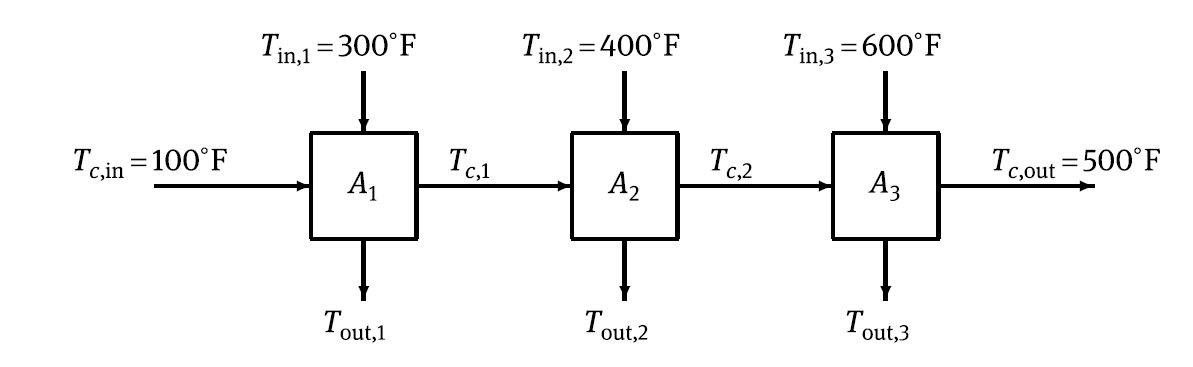

In order to save energy, three heaters are expected such that the sum of the heated areas A1 + A2 + A3 is minimized

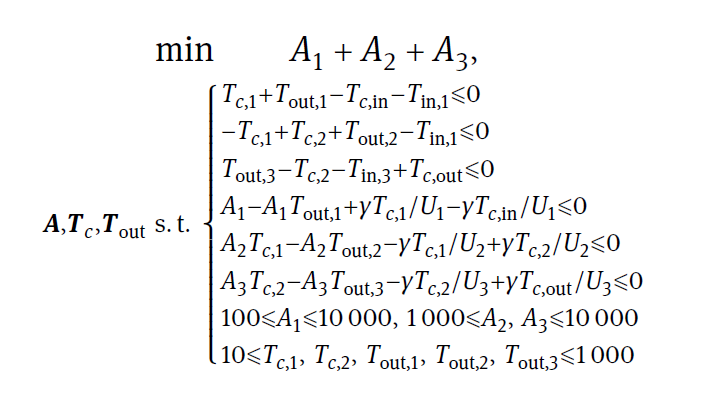

where γ = 105, U1 = 120, U2 = 80, and U3 = 40.

% parameters
gama=1e5; U=[120,80,40]; 
Tcin=100; T1in=300; T2in=400; T3in=600; Tcout=500;

% inital guess
Surf0 = [150, 150, 1000];        % [S1,S2,S3]
TC0   = [200, 300      ];        % [S4,S5]
Tout0 = [200, 300, 500 ];        % [S6,S7,S8]
x0 = [Surf0, TC0, Tout0];

% problem formulation

% HX surface is described as 'S', bc 'A' is used as inequlity matrix
fun = @(S)S(1)+S(2)+S(3)

fun = function_handle with value:
    @(S)S(1)+S(2)+S(3)



% S  1 2 3 4 5 6 7 8
A = [0,0,0,1,0,1,0,0;
     0,0,0,-1,1,0,1,0;
     0,0,0,0,-1,0,0,1];
b = [Tcin+T1in;
     T1in;
     T3in-Tcout];

Aeq = [];
beq = [];

lb = [1000 , 1000 , 1000 , 10  , 10  , 10  , 10  , 10  ];
ub = [10000, 10000, 10000, 1000, 1000, 1000, 1000, 1000];
%      S1    S2     S3     S4    S5    S6    S7    S8

nonlcon = @nonlconFun;
%nonlcon = [];
options = optimoptions('fmincon','Display','iter');

x = fmincon(fun,x0,A,b,Aeq,beq,lb,ub,nonlcon,options);

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       9    3.002970e+03    2.998e+05    5.000e-01
    1      18    3.003025e+03    2.996e+05    5.044e-01    1.532e-01
    2      27    3.004532e+03    2.986e+05    5.050e-01    1.950e+00
    3      36    3.013798e+03    2.943e+05    5.050e-01    9.333e+00
    4      45    3.223876e+03    2.332e+05    5.050e-01    1.651e+02
    5      54    3.280999e+03    2.291e+05    5.050e-01    3.631e+01
    6      63    6.550938e+03    1.360e+05    5.122e-01    2.088e+03
    7      72    8.084679e+03    7.421e+04    6.055e-01    9.754e+02
    8      81    9.831284e+03    2.789e+02    7.989e-01    1.111e+03
    9      90    9.827962e+03    5.850e+02    7.986e-01    2.038e+00
   10      99    9.793251e+03    0.000e+00    7.954e-01    2.073e+01
   11    

fprintf('Optimal heating surface of Heat Exchanger: A1 = %g, A2 = %g, A4 = %g',x(1),x(2),x(3))

Optimal heating surface of Heat Exchanger: A1 = 1026.95, A2 = 1000, A4 = 5485.28

fprintf('The temperature of intermediate streams: T_C1 = %g, T_C2 = %g',x(4),x(5))

The temperature of intermediate streams: T_C1 = 265.06, T_C2 = 280.589

fprintf('The outlet temperatures: T_OUT1 = %g, T_OUT2 = %g, T_OUT3 = %g',x(6),x(7),x(8))

The outlet temperatures: T_OUT1 = 134.94, T_OUT2 = 284.471, T_OUT3 = 380.589

function [c,ceq] = nonlconFun(S)

    gama=1e5; U=[120,80,40]; 
    Tcin=100; T1in=300; T2in=400; T3in=600; Tcout=500;

    c = [ S(1)-S(1)*S(6)+gama*S(4)/U(1)-gama*Tcin/U(1);
          S(2)*S(4)-S(2)*S(7)-gama*S(4)/U(2)+gama*S(5)/U(2);
          S(3)*S(5)-S(3)*S(8)-gama*S(5)/U(3)+gama*Tcout/U(3)];
  
  ceq = [];
end